# **demo04 of Im2mesh package**

demo04 - What is inside im2mesh.

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com   [Project website](https://github.com/mjx888/im2mesh)   [List of demo](https://mjx888.github.io/im2mesh_demo_html/demo_list.html)

## Note

I suggest familiarizing yourself with [Im2mesh_GUI](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh) before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package. No need to install any MATLAB toolboxes when running this demo.

## Initialize

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size (optional).

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function bounds2mesh use a mesh generator called MESH2D (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Image

Let's start demo. Import image.

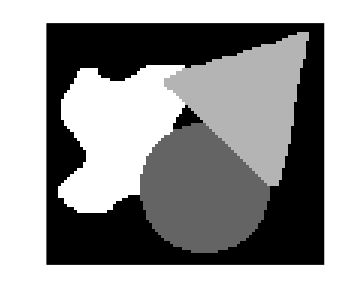

im = imread('Shape.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

## Inside function im2mesh

Function im2mesh has incorporated the workflow that you saw in im2mesh_GUI: extract polygonal boundaries from image, search & label control points, smooth boundary, simplify boundary, select phase, and generate mesh.

### Extract boundaries

We use function im2Bounds to extract boundaries.

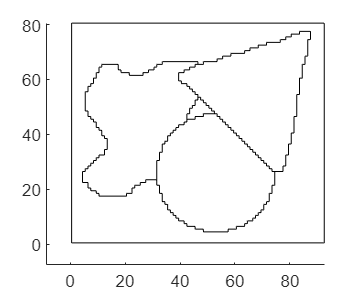

% image to polygon boundary
boundsRaw = im2Bounds( im );
% plot boundary using plotBounds
plotBounds(boundsRaw);

We can use function totalNumVertex to get total number of vertices in boundsRaw.

totalNumVertex(boundsRaw)

ans = 1320

### Find control points

We use function getCtrlPnts to find and label control points.

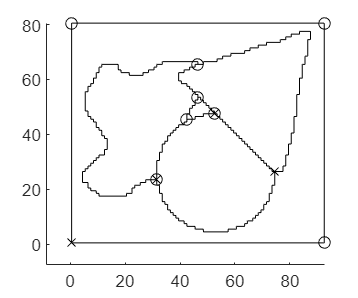

% label control points
tf_avoid_sharp_corner = false;
boundsCtrlP = getCtrlPnts( boundsRaw, tf_avoid_sharp_corner, size(im) );

plotBounds(boundsCtrlP, true);     % show starting and control points

We can use function totalNumCtrlPnt to get total number of control points.

totalNumCtrlPnt(boundsCtrlP)

ans = 22

### Smooth boundary

We use function smoothBounds to smooth boundary.

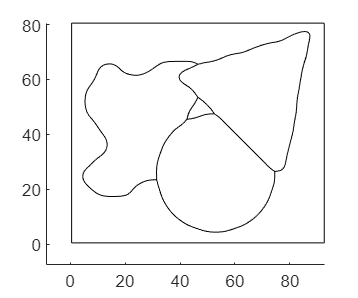

lambda = 0.5;
mu = -0.5;
iters = 100;
thresh_turn  = 0;
thresh_vert_smooth  = 0;

boundsSmooth = smoothBounds( boundsCtrlP, lambda, mu, iters, ...
                thresh_turn , thresh_vert_smooth );

plotBounds(boundsSmooth);

### Simplify boundary

We use function simplifyBounds to simplify boundary. Other operation shown here is used to clear up redundant vertices.

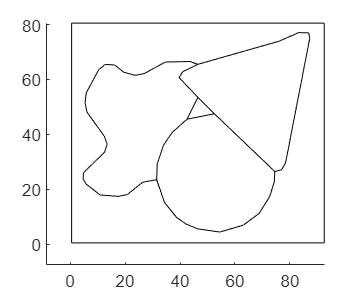

% simplify polygon boundary
tolerance = 0.5;
thresh_vert_simplify = 0;
boundsSimplified = simplifyBounds( boundsSmooth, tolerance, ...
                                        thresh_vert_simplify );
boundsSimplified = delZeroAreaPoly( boundsSimplified );

% clear up redundant vertices
% only control points and turning points will remain
boundsClear = getCtrlPnts( boundsSimplified, false );
boundsClear = simplifyBounds( boundsClear, 0 );

plotBounds(boundsClear);

We can use function totalNumVertex to get total number of vertices in boundsClear.

totalNumVertex(boundsClear)

ans = 104

clearvars

## A simpler operation

As shown in example3 of demo01, the above operations can be simplifed if we are only interested in boundary.

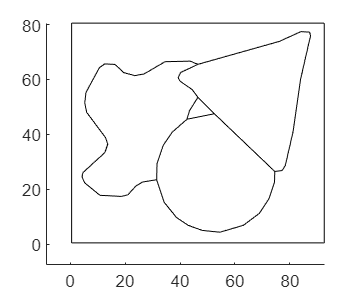

im = imread('Shape.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end

opt = [];                       % reset opt
opt.tf_avoid_sharp_corner = false;
opt.lambda = 0.5;
opt.mu = -0.53;
opt.iters = 100;
opt.thresh_turn = 0;
opt.thresh_vert_smooth = 0;
opt.tolerance = 0.5;
opt.thresh_vert_simplify = 0;
opt.select_phase = [];
opt.grad_limit = 0.25;
opt.hmax = 500;
opt.mesh_kind = 'delaunay';

opt.tf_mesh = false;            % do not generate mesh

% bounds is the simplified polygonal boundary
bounds = im2mesh( im, opt );

plotBounds( bounds );

### Area percentage

We can use the following code to calculate area perccentage.

% column vector for intensity
intensity = unique( im ); 

% calculate the area perccentage of grayscale in image
percent_pixel = getPixelPercent( im );

% calculate the area perccentage in simplified polygonal boundary
percent_polyarea = getPolyShapePercent( bounds );

% create table
T = table( intensity, percent_pixel, percent_polyarea );
 
% show table
T

T = 4×3 table
    intensity    percent_pixel    percent_polyarea
    _________    _____________    ________________

         0          46.658             46.739     
       100          17.989              17.88     
       180          17.255              17.32     
       255          18.098             18.062     


Function getPixelPercent is used to calculate the area perccentage of grayscale in an image. 

Function getPolyShapePercent is used to calculate the area perccentage in simplified polygonal boundary. 

We saw minor changes in area perccentage. That's good.

## Generate mesh

We can use function bounds2mesh to generate mesh. 

hmax = 500;
grad_limit = 0.25;

[ vert,tria,tnum ] = bounds2mesh( bounds, hmax, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                 86                108
         10                102                242
         11                102                244


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                169                108
         10                169                108
         18                176                934


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
         10                  0                920



Plot mesh using function plotMeshes

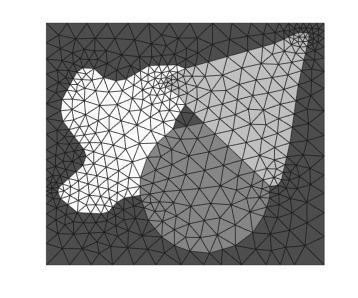

plotMeshes(vert,tria,tnum)

Zoom in

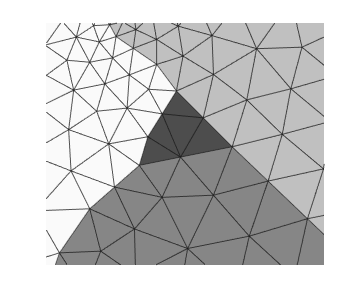

plotMeshes(vert,tria,tnum)
xlim([32.5 62.4])
ylim([34.8 60.8])

## Refine mesh

We can refine the mesh near a specific polyline. We will show more about this in demo16 and demo17.

### Insert nodes into a polyine

Suppose we are interested in polygon - bounds{1}{3}.

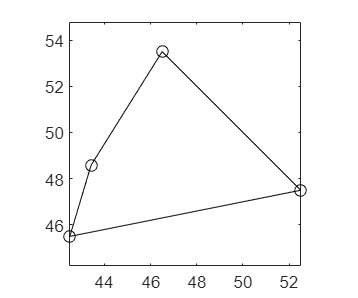

poly = bounds{1}{3};
plot( poly(:,1), poly(:,2), 'ko-' ); axis equal

We can add mesh seeds/nodes to the interested polyline. We do this by function insertEleSizeSeed.

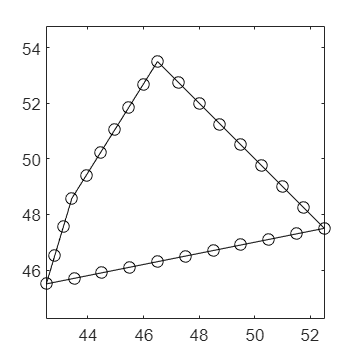

target_size = 1;  % space between seeds
polyNew = insertEleSizeSeed( poly, target_size );

plot( polyNew(:,1), polyNew(:,2), 'ko-' ); axis equal

We use function addPnt2Bound to insert polyNew into global boundaries.

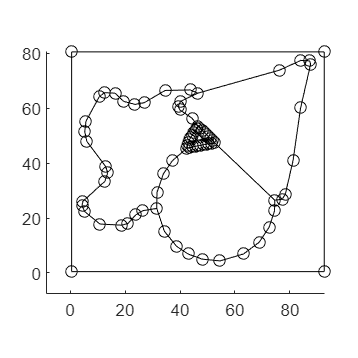

tol_dist = 1e-2;    % distance tolerance
boundsNew = addPnt2Bound( polyNew, bounds, tol_dist );

% show all vertices
plotBounds( boundsNew, false, 'ko-' );  

### Generate mesh again

grad_limit = 0.25;
hmax = 500;

[ vert,tria,tnum ] = bounds2mesh( boundsNew, hmax, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                109                154
         10                126                318
         15                129                372


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
         10                200                154
         10                200                154
         20                207               1308
         21                207               1310


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
         10                  0               1292



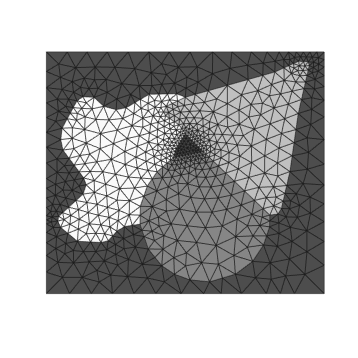


plotMeshes(vert,tria,tnum);

Zoom in

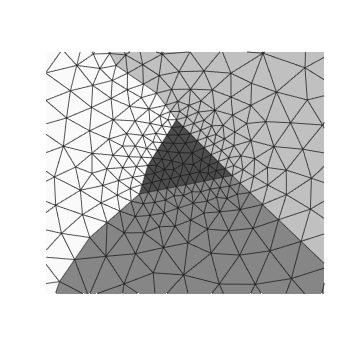

plotMeshes(vert,tria,tnum)
xlim([32.5 62.4])
ylim([34.8 60.8])

Awesome!

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo